The purpose of this script is to create a model for harmonic motion and observe the effects of changing the parameters. A hand-waving style introduction is needed before this however. We will stay away from the math equations as this is here for intuition and not about solving differential equations. During the script we will change the spring constant, coefficient of friction and the driving force in order to observer different types of harmonic motion. First off,let's take a look briefly at our simulink model:

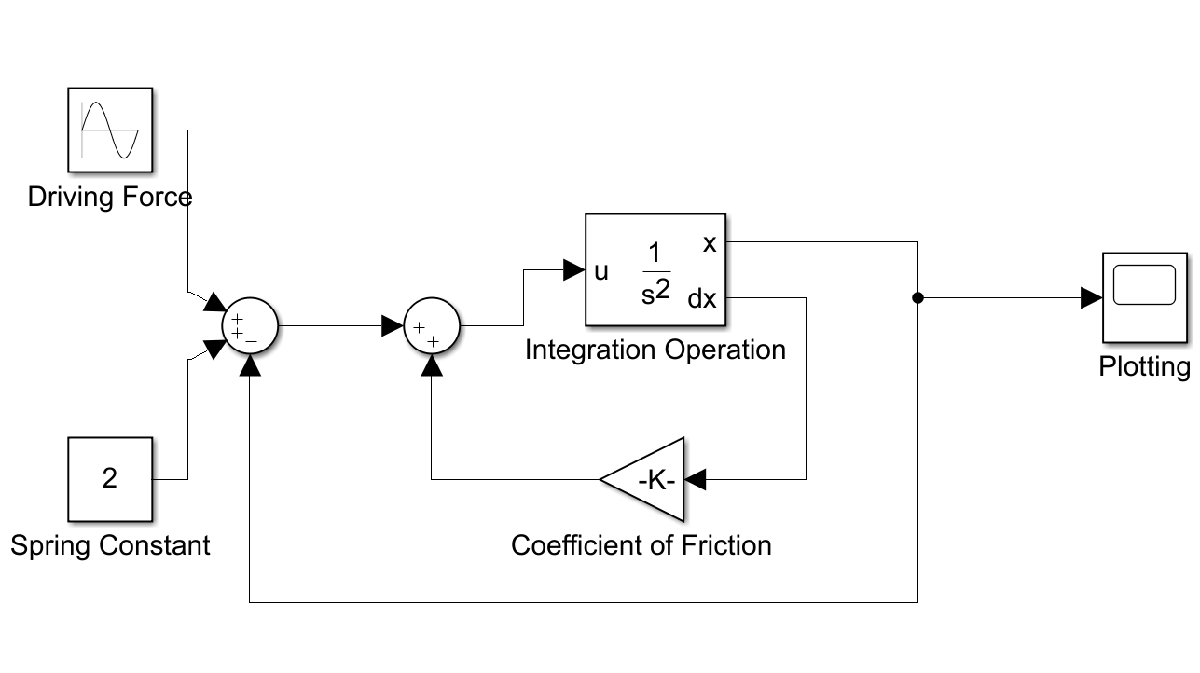

Starting from simple and working our way up:

- On the far right, we have the plotting tool, this will plot the results of the simulation for us. It is plotting the distance of the object as a function of time. 

- On the far left, the spring constant. The units don't matter here.

- In the middle, we have our friction coefficient, in this case think of it as how much friction is created by dragging a block

- Feedback loops in the left-middle. These control if the signal is added or subtracted to the input signal

- Top left, the driving force. this is a function that will apply force to our system.

- Top middle, our integrator. This will be numerically integrating the signal that is recieved as input. The input signal here is the force action of the object in the system.

First, we are going to observe simple harmonic motion

%the following parameters are setting up this system to illustrate simple
%harmonic motion. This is the type of motion that will be observed by
%ignoring friction and absent of driving force.
model='HM_model.slx';
obj=load_system(model);
set_param('HM_model/Driving Force','Amplitude','0')
set_param('HM_model/Spring Constant','Value','3')
set_param('HM_model/Coefficient of Friction','Gain','0')
set_param(bdroot,'SimulationCommand','Update')
open_system(model) %this will open a simulink window
output=sim(model);
save_system(model);

Now popping over to the model, let's observe simple harmonic motion. Recall that this is the case where there is no driving force and the system has no friction. This implies that the system will oscillate indefinitely. Go ahead and run the above block of code and observe the output from the model. It should be this:

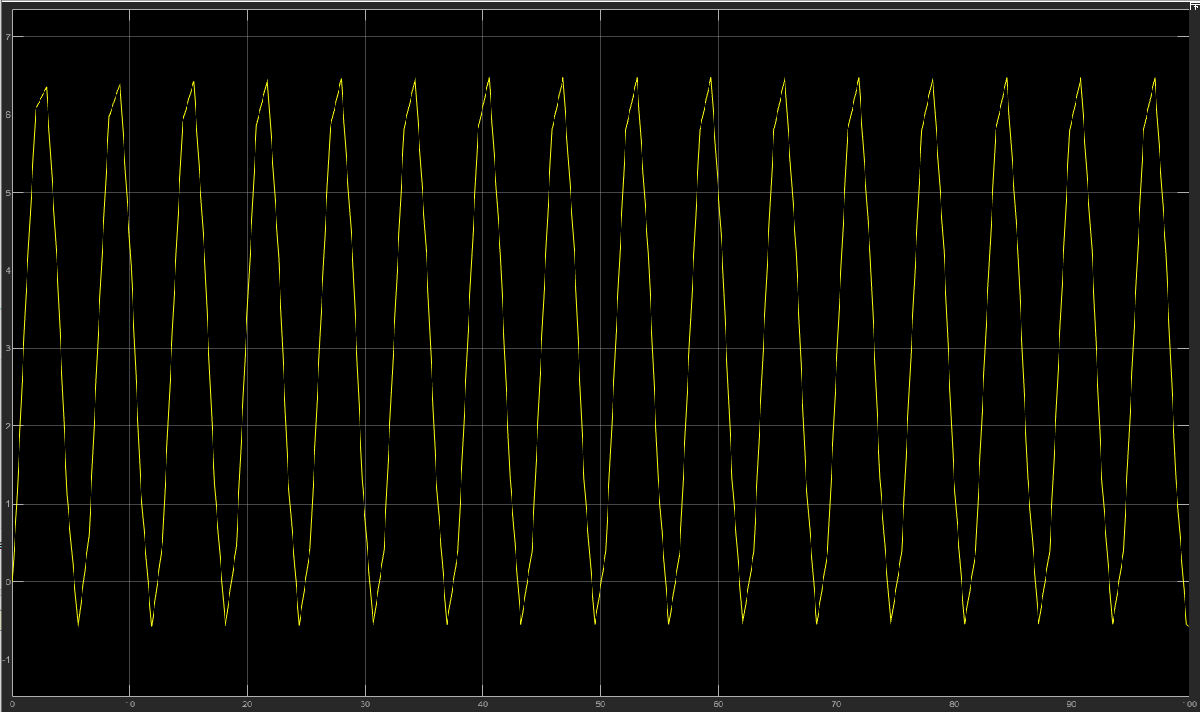

It is somthing with a steady period with an amplitude that does not change and is the simplest for of motion that will be observed today. Unfortunately, nothing in the world can move without some form of friction being applied to it. Therefore, we will include this in the model. Friction is a funtion of the velocity of the system. The higher the velocity, the higher the friction. As the friction increases we will see the amplitude begin to decay. Looking at the model, we can see a negative feedback loop attached to the velocity. The dx output from the second order integrator is the speed associated with the acceleration that we are integrating. 

%we now want to observe the effects of applying friction to our model, this
%can be done by adjusting the coefficient of friction. It will weight the
%effect that velocity has on the acceleration of the object. 
close_system
model='HM_model.slx';
obj=load_system(model);
set_param('HM_model/Driving Force','Amplitude','0')
set_param('HM_model/Spring Constant','Value','3')
set_param('HM_model/Coefficient of Friction','Gain','-0.1')
set_param(bdroot,'SimulationCommand','Update')
open_system(model) %this will open a simulink window
output=sim(model);
save_system(model);

So, what is the important observable after adding some friction related to velocity? Well the first is that the period of oscillation is not changing. The second being that our amplitude is decaying over time to eventually reach zero. This is what will happen after we give a spring system a shove, or we provide  a pendulum with some kinetic energy. The resulting pattern look like this:

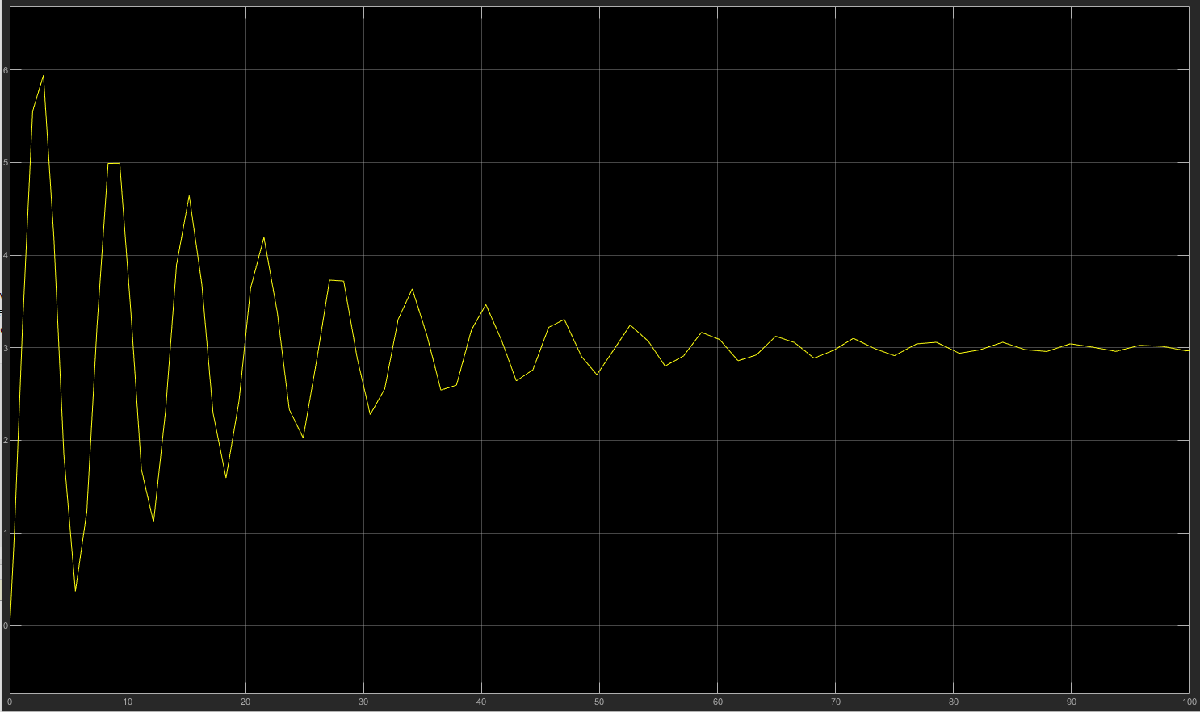

This is the case of damped harmonic motion. Over time, the amplitude is decaying due to the forces of friction which are acting on the object. Open up the simulation and play around with the coeifficient of friction. It is currently negative, what happens if it become positive?(this would be where friction causes something to accelerate). What happens when we make the value larger or smaller? Play around with the model in order to observe the effects. 

    The next interesting feature of harmonic motion is attaching a driver to it. Imaging giving our pendulum a push each time it returns to the center point. Instead of having a decaying amplitude over time, we could find a balance between the force of friction and the driving force in order to obtain balance somewhere. We can have a case where our driving force exites the normal model of the pendulum which will cause the amplitude to explode. Grab the formula for the natural frequency of an object and match it in the model to obseve the effects. The following is known as forced or driven harmonic motion. 

%this block will illustrate the effect of driven or forced harmonic motion.
%
close_system
model='HM_model.slx';
obj=load_system(model);
set_param('HM_model/Driving Force','Amplitude','2')
set_param('HM_model/Spring Constant','Value','3')
set_param('HM_model/Coefficient of Friction','Gain','-0.1')
set_param(bdroot,'SimulationCommand','Update')
open_system(model) %this will open a simulink window
output=sim(model);
save_system(model);

The interesting part observe here is how we acheive equilibrium between the driver and the force of friction. The waves from the 50-100 seconds mark appear as if being simple harmonic motion, but we have in fact obtained a balance between the driving force and the friction force. 

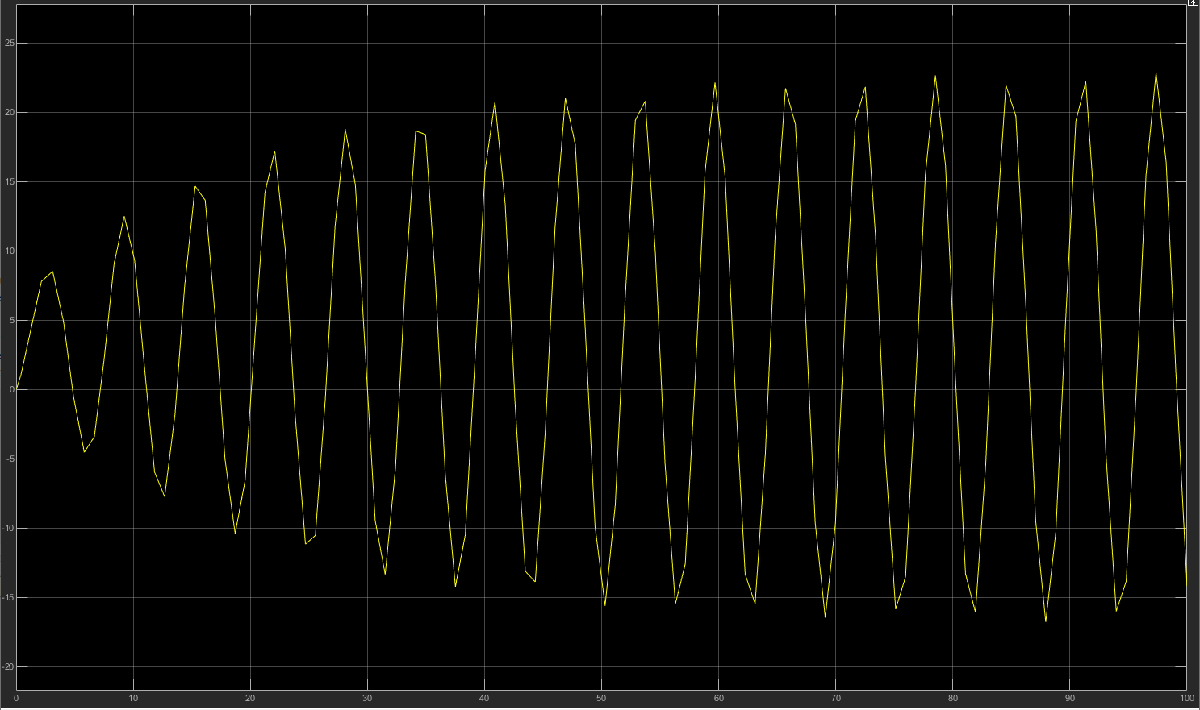

Go into the model and play around with the driving force amplitude and the driving force frequency, let's see what happens when we match the driving frequency to that of the natural frequency of the object. Image you're trying to make the biggest wave possible in a bath tub, that is what we're going to replicate here. 

%we are going to set the friction force to zero, we are going to ignore it
%to observe the effect of natural frequency. 
close_system
model='HM_model.slx';
obj=load_system(model);
set_param('HM_model/Driving Force','Amplitude','5.0')
set_param('HM_model/Driving Force','Frequency','1.0')
set_param('HM_model/Spring Constant','Value','3.0')
set_param('HM_model/Coefficient of Friction','Gain','0.0')
set_param(bdroot,'SimulationCommand','Update')
open_system(model) %this will open a simulink window
output=sim(model);
save_system(model);

The effect of getting close to the natural frequency is the following:

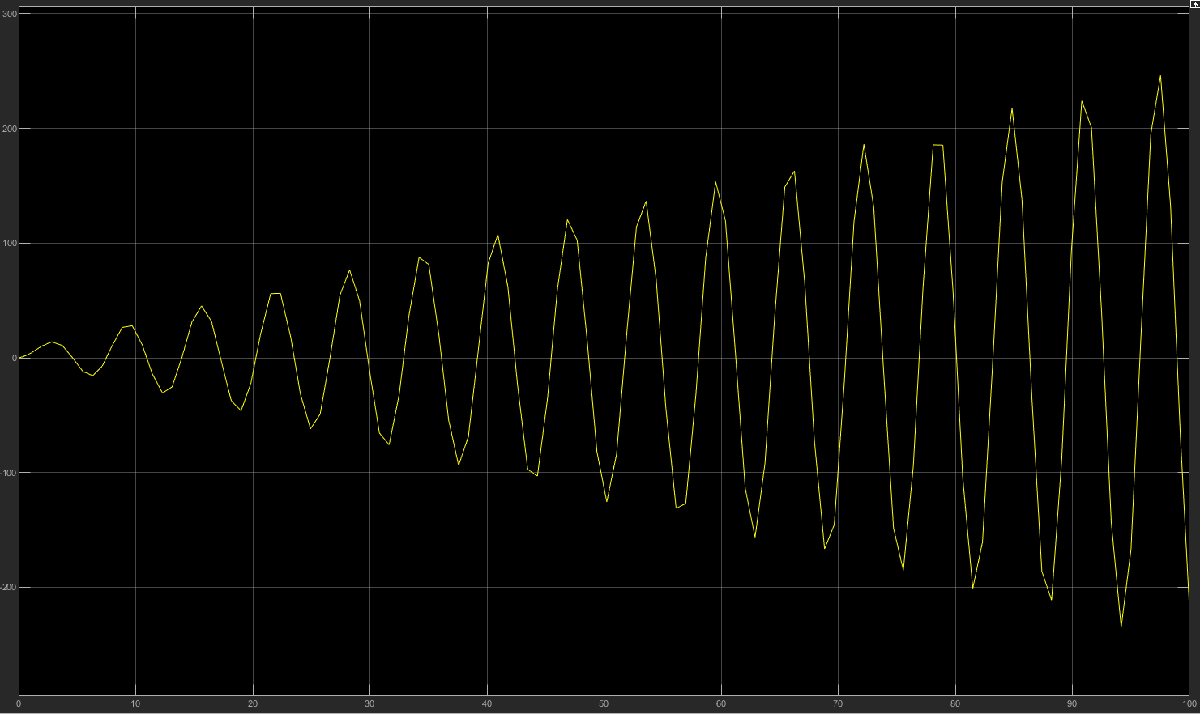

We have an exponential run away of the amplitude of the oscillator as we are being reinforced continuousl at the correct place. The next example, we will look at a driving force that is nowhere near the natural frequency and show that over time, the driving force will create a steady state solution when there is friction involved. When we removed this, we can observe the initial frequency fighting with the driven frequency over the course of time. The following image illustrates this effect. Run the simulation and play around witht the frequency of our oscilator.  

%This will show the fighting of the driver and the initial frequency.
close_system
model='HM_model.slx';
obj=load_system(model);
set_param('HM_model/Driving Force','Amplitude','5.0')
set_param('HM_model/Driving Force','Frequency','0.33')
set_param('HM_model/Spring Constant','Value','3.0')
set_param('HM_model/Coefficient of Friction','Gain','0.0')
set_param('HM_model', 'StopTime', '1000')
set_param(bdroot,'SimulationCommand','Update')
open_system(model) %this will open a simulink window
output=sim(model);
save_system(model);

The result of this is the follwing: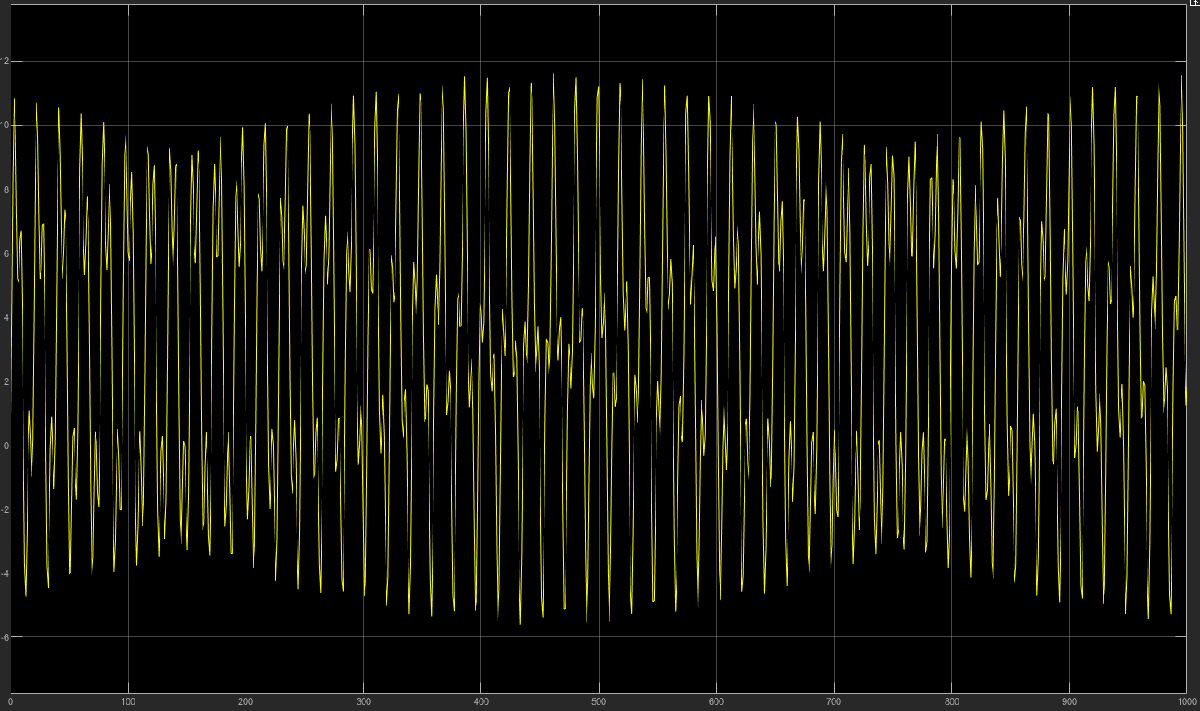

We can see the trend of two frequencies duelling out. How slowly over time is changes the peak location and then back again. Open up the model and play with the frequency slider. Add in some friction, change the driver amplitude and really play around. The goal of this model is to gain intuition about harmonic motion by using the ability to rapidly simulate and observe the effects of this simulation instead of using a bunch of mathematical equations.

    Thank you for reading through. I hope this helps provide a more intuitive understanding of harmonic motion. 